## Crossover system

### Lavpas

#### Design

clearvars
clf

cutoff=500;

R1=10e+3;
syms C;

C1=solve(cutoff==1/(R1*C))

$$C1 = \frac{1}{5000000}$$

fprintf("C1=%dnF\n",(C1*power(10,9)))

C1=200nF


#### Test af ordner

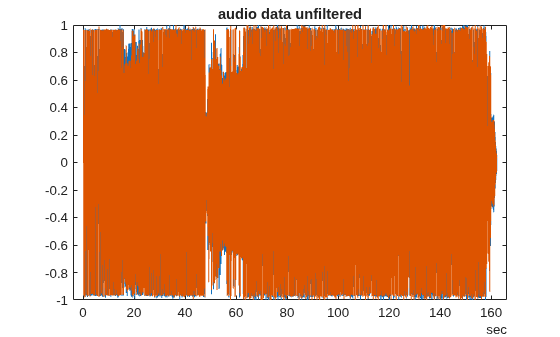

clearvars
clf

[y,Fs] = audioread("drikkerSomEtSvin.wav");
info=audioinfo("drikkerSomEtSvin.wav");
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
plot(t,y)
title("audio data unfiltered")

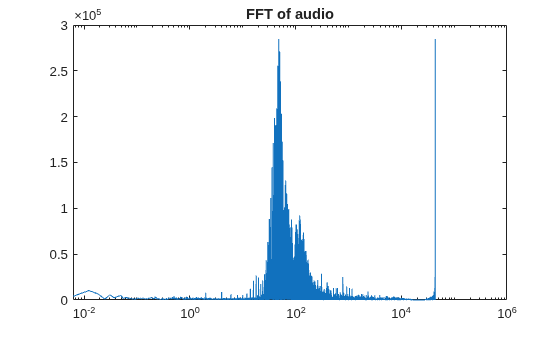


L=info.Duration;


ly=y(:,1).';
lY=fft(ly);

L=length(lY);
plot(Fs/L*(0:L-1),abs(lY))
xscale log
title("FFT of audio")

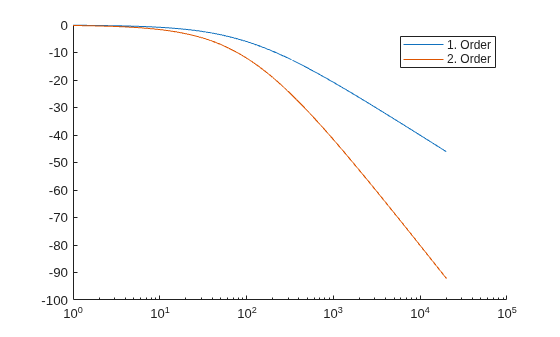


clf

cutoff=100;
Q=0.5;

syms s;
H1= @(s) 1./(s/cutoff+1);

H2= @(s) 1./(power(s,2)/power(cutoff,2)+s/(Q*cutoff)+1);

s1=1:0.01:20e+3;

hold on

plot(s1,20*log10(H1(s1)))
plot(s1,20*log10(H2(s1)))

xscale log
legend("1. Order","2. Order")
hold off

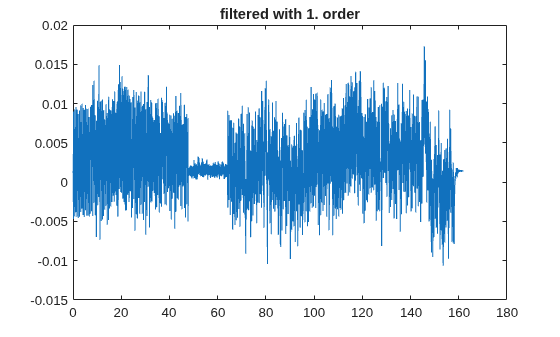


w=0:1:length(lY)-1;

clf
t=linspace(0,info.Duration,L);
yH1=ifft(lY.*H1(j*w));
plot(t,real(yH1))
title("filtered with 1. order")


% sound(y,Fs)
% sound(real(yH1),Fs)

## Butterworth Cauer topology test

clearvars
clf

% order
n = 4;
wc = 2*pi*100;

gk = @(k) 2*sin((2*k-1)*pi/(2*n)); % k is odd for series inductor, even for shunt cap

gv = zeros(1,n);

for k = 1:1:n
    gv(k)=gk(k)/wc;
    fprintf("k%d: %e\n", k, gv(k))
end

k1: 1.218119e-03
k2: 2.940800e-03
k3: 2.940800e-03
k4: 1.218119e-03


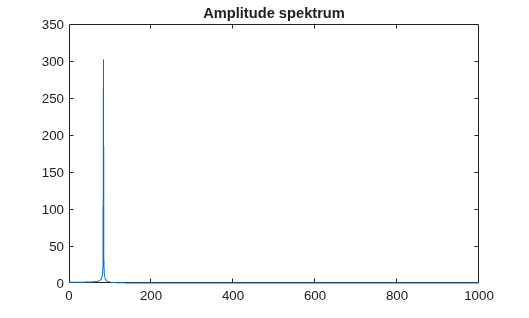


R1=1;
L1=gv(1);
L2=gv(3);
C1=gv(2);
C2=gv(4);

H = @(s) 1./(C1.*C2.*s.^2.*(L2.*s+1./(C2.*s)).*(R1+L1.*s+1./(C1.*s)));

f=linspace(1,1000,1000);

plot(f,abs(H(2*pi*f*j)))
title("Amplitude spektrum")


% Transfer test
clearvars
clf

syms s R1 L1 C1 L2 C2 Vo Zc2 Zl2 V1 Vin Zc1 Zc1 Zeq Zr1 Zl1 w;
Zr1=R1;
Zl1=s*L1;
Zc1=1/(s*C1);
Zl2=s*L2;
Zc2=1/(s*C2);

Zeq=Zr1+Zl1;

V1=Vin*Zc1/(Zeq+Zc1);

l=Vo==V1*Zc2/(Zl2+Zc2)

$$l = \mathrm{Vo}=\frac{\mathrm{Vin}}{C_{1}\,C_{2}\,s^{2}\,\left(L_{2}\,s+\frac{1}{C_{2}\,s}\right)\,\left(R_{1}+L_{1}\,s+\frac{1}{C_{1}\,s}\right)}$$


H=l/Vin

$$H = \frac{\mathrm{Vo}}{\mathrm{Vin}}=\frac{1}{C_{1}\,C_{2}\,s^{2}\,\left(L_{2}\,s+\frac{1}{C_{2}\,s}\right)\,\left(R_{1}+L_{1}\,s+\frac{1}{C_{1}\,s}\right)}$$